clear
close all

syms a b c f positive
syms t real
syms x(t) y(t)


% ode1 = diff(x,t) == a*x -b*x*y
% ode2 = diff(y,t) == m*y - n*x*y


ode1 = diff(x,t) == a*x(b/y - x)

$$ode1(t) = \frac{\partial }{\partial t}x\left(t\right)=a\,x\left(\frac{b}{y\left(t\right)}-x\left(t\right)\right)$$

ode2 = diff(y,t) == c * y(f*x - y)

$$ode2(t) = \frac{\partial }{\partial t}y\left(t\right)=c\,y\left(f\,x\left(t\right)-y\left(t\right)\right)$$

odes = [ode1; ode2]

$$odes(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)=a\,x\left(\frac{b}{y\left(t\right)}-x\left(t\right)\right)\\ \frac{\partial }{\partial t}y\left(t\right)=c\,y\left(f\,x\left(t\right)-y\left(t\right)\right) \end{array}\right)$$

a0 = 1

a0 = 1

b0 = 20000

b0 = 20000

c0 = 1

c0 = 1

f0 = 30

f0 = 30

odes1 = subs(odes, [a b c f], [a0 b0 c0 f0])

$$odes1(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)=x\left(\frac{20000}{y\left(t\right)}-x\left(t\right)\right)\\ \frac{\partial }{\partial t}y\left(t\right)=y\left(30\,x\left(t\right)-y\left(t\right)\right) \end{array}\right)$$

V = odeToVectorField(odes1)

$$V = \left(\begin{array}{c} Y_{1}\left(30\,Y_{2}-Y_{1}\right)\\ Y_{2}\left(\frac{20000}{Y_{1}}-Y_{2}\right) \end{array}\right)$$

$$V = \left(\begin{array}{c} Y_{1}\left(30\,Y_{2}-Y_{1}\right)\\ Y_{2}\left(\frac{20000}{Y_{1}}-Y_{2}\right) \end{array}\right)$$

Yode = matlabFunction(V, 'vars', {'t','Y'})

错误使用 symengine
错误: 使用括号 '()' 进行索引必须作为有效索引表达式的最后一个操作出现。

出错 symengine

出错 sym/matlabFunction (line 190)
    g = symengine('makeFhandle',varnames,body);

tspan = [0 10];
x0 = 10;
y0 = 1;

[t,Y] = ode45(Yode, tspan, [x0;y0])

函数或变量 'Yode' 无法识别。

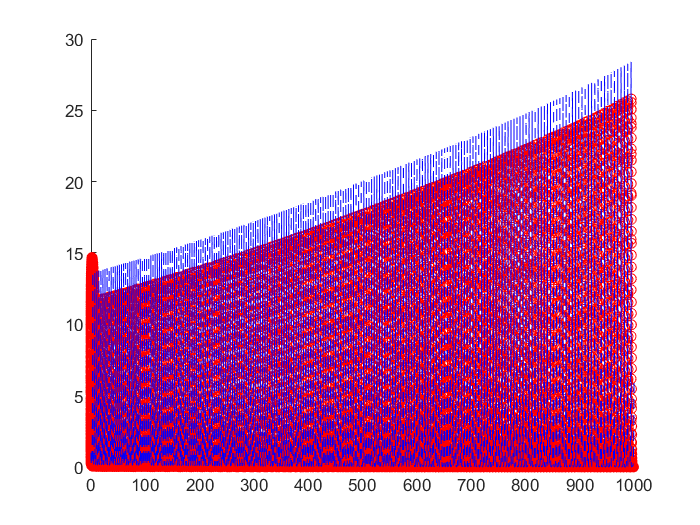

plot(t,Y(:,1), '-ro', t,Y(:,2), '--b')

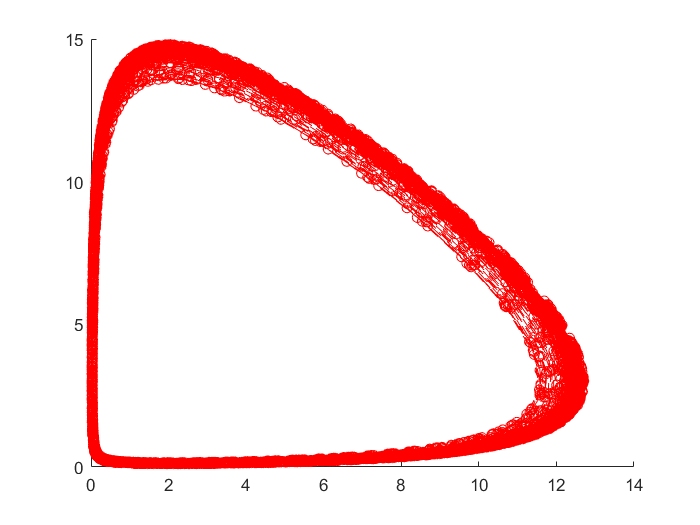

figure
hold on
plot(Y(:,1),Y(:,2),'--ro')